## Estudando conteúdo P2

s = tf('s');
G = (1 / (s*(s+1)*(s+10)))

G =
 
           1
  -------------------
  s^3 + 11 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


**Efeito do aumento do ganho K**

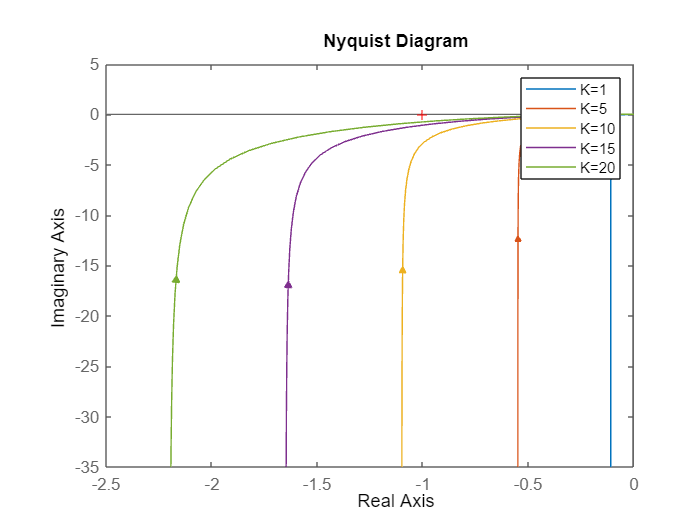

K1 = 5;
K2 = 10;
K3 = 15;
K4 = 20;

nyq=nyquistplot(G, G*K1, G*K2, G*K3, G*K4); legend('K=1','K=5','K=10','K=15','K=20')
set(nyq,'ShowFullContour','off')

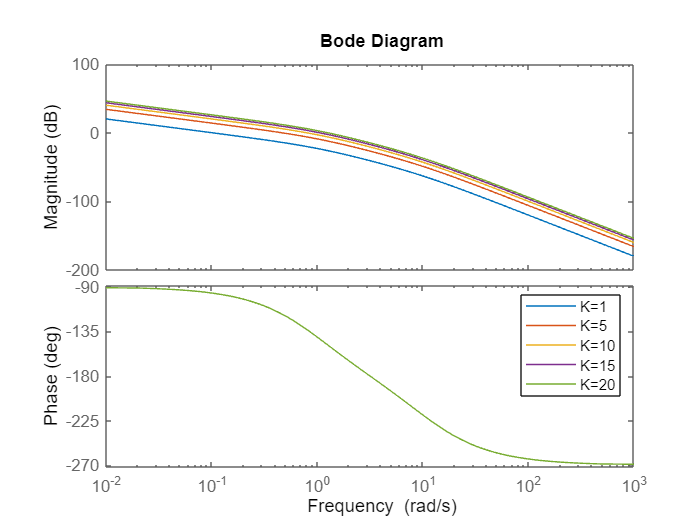

bode(G, G*K1, G*K2, G*K3, G*K4); legend('K=1','K=5','K=10','K=15','K=20')

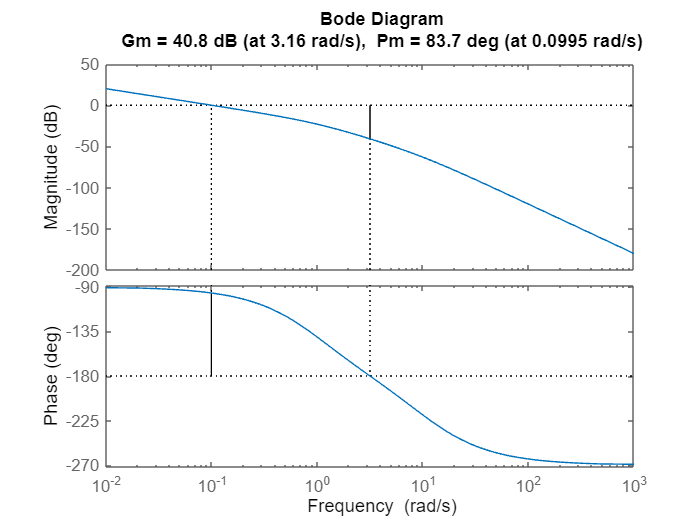

margin(G)

- Aumento do módulo

- Não altera a fase

**Efeito do K negativo**

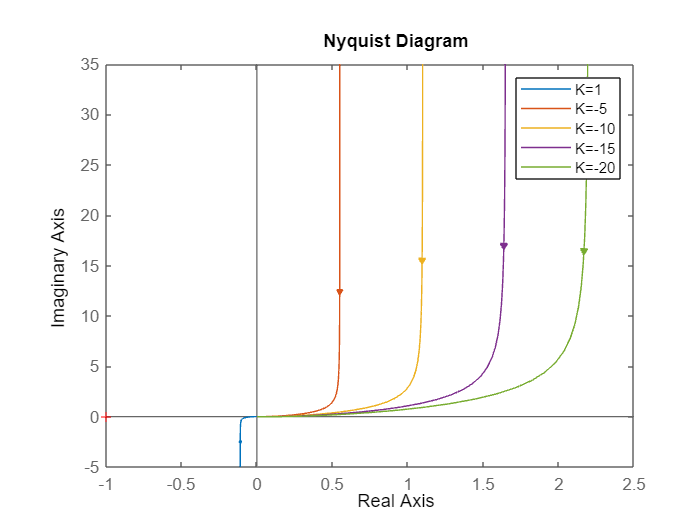

K1 = -5;
K2 = -10;
K3 = -15;
K4 = -20;

nyq=nyquistplot(G, G*K1, G*K2, G*K3, G*K4); legend('K=1','K=-5','K=-10','K=-15','K=-20')
set(nyq,'ShowFullContour','off')

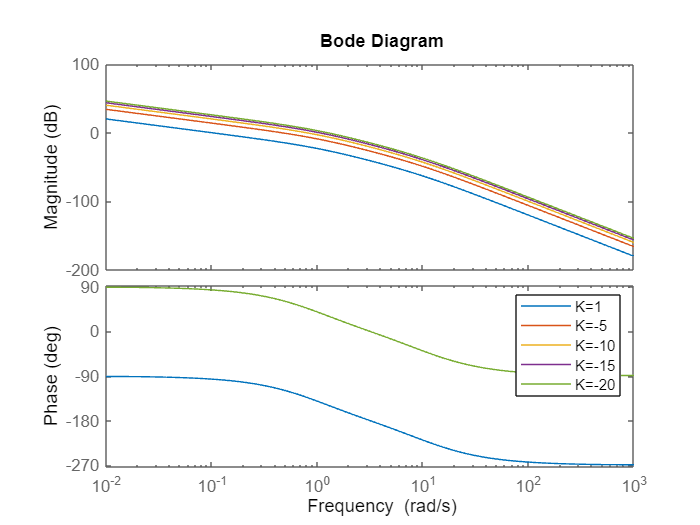

bode(G, G*K1, G*K2, G*K3, G*K4); legend('K=1','K=-5','K=-10','K=-15','K=-20')

- Permanece o aumento do módulo

- A fase é acrescida de 180º

G2 = (1 / (s+0.5))

G2 =
 
     1
  -------
  s + 0.5
 
Continuous-time transfer function.
Model Properties


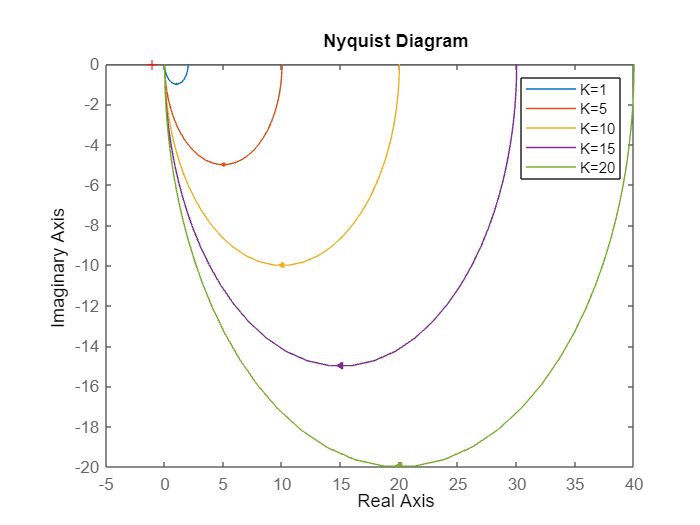

K1 = 5;
K2 = 10;
K3 = 15;
K4 = 20;

nyq=nyquistplot(G2, G2*K1, G2*K2, G2*K3, G2*K4); legend('K=1','K=5','K=10','K=15','K=20')
set(nyq,'ShowFullContour','off')

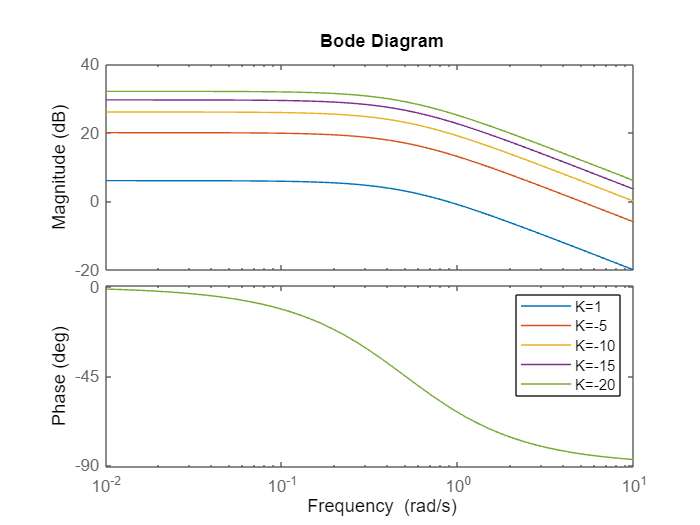

bode(G2, G2*K1, G2*K2, G2*K3, G2*K4); legend('K=1','K=-5','K=-10','K=-15','K=-20')

## P2 23/1

Questão 1

s = tf('s');
G1 = (((s+200)^2)/(s*(s+1)*(s+10000)*(s+100000)))

G1 =
 
          s^2 + 400 s + 40000
  ------------------------------------
  s^4 + 110001 s^3 + 1e09 s^2 + 1e09 s
 
Continuous-time transfer function.
Model Properties


K=31.52 

K = 31.5200

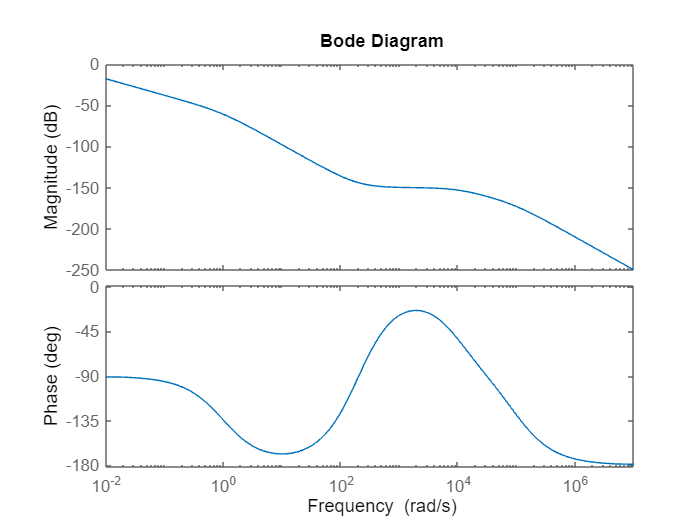

bode(K*G1)

G3 = (3-2*s)/(s^2+s+1)

G3 =
 
   -2 s + 3
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.
Model Properties


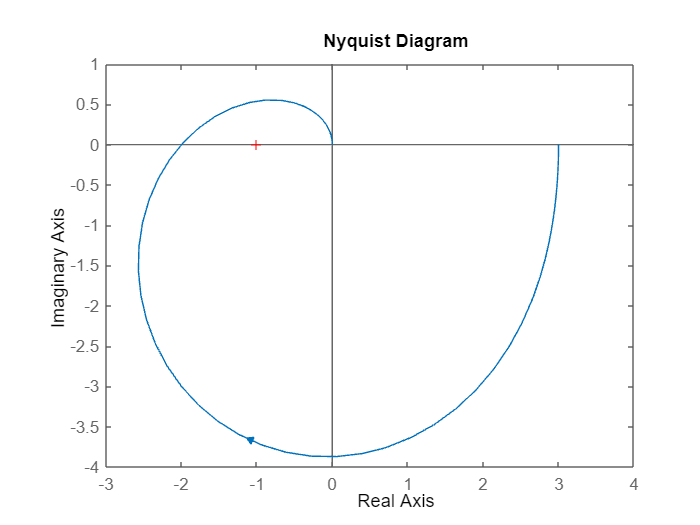

nyq=nyquistplot(G3);
set(nyq,'ShowFullContour','off')

## P2 - 2018

G4 = (s+1)/(s^2*(s+100))

G4 =
 
      s + 1
  -------------
  s^3 + 100 s^2
 
Continuous-time transfer function.
Model Properties


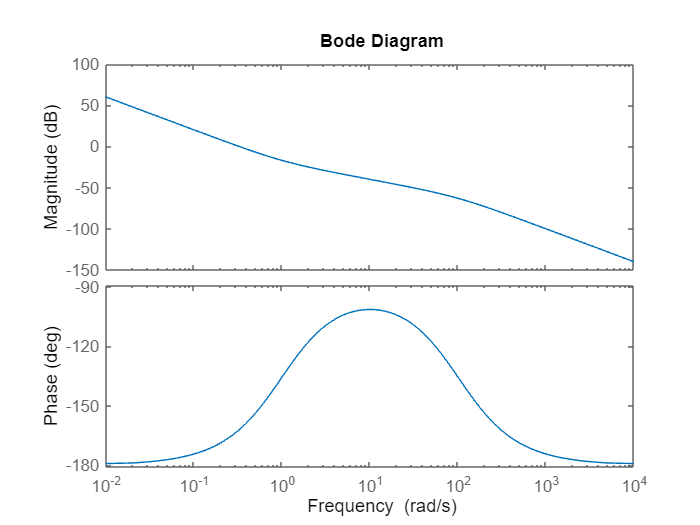

K = 10;
bode(K*G4)